## Problem 3 MATLAB Live Script

Bowen Jiang

Read the atmosphere data from [https://www.digitaldutch.com/atmoscalc/table.htm,](https://www.digitaldutch.com/atmoscalc/table.htm,) then interpolate

T = readtable("data.csv");
height = 1000 * table2array(T(:,1));  % m
rho = table2array(T(:,2));  % kg/m^3
mu = table2array(T(:,3));  % Pa*s

height_rho = spline(height, rho);
height_mu = spline(height, mu);

Define variables

The diameter of the bowling ball is 8.5in (0.216m), the weight is between 8 and 16 lbs

m = 6;  % kg
g = 9.8;  % m/s^2
d = 0.216;  % m
h0 = 30000 / 2.54;  % m
V0 = 0; % m/s
A = pi * (d/2)^2;  % m^2, area of the sphere

Test the function we defined for $C_D$

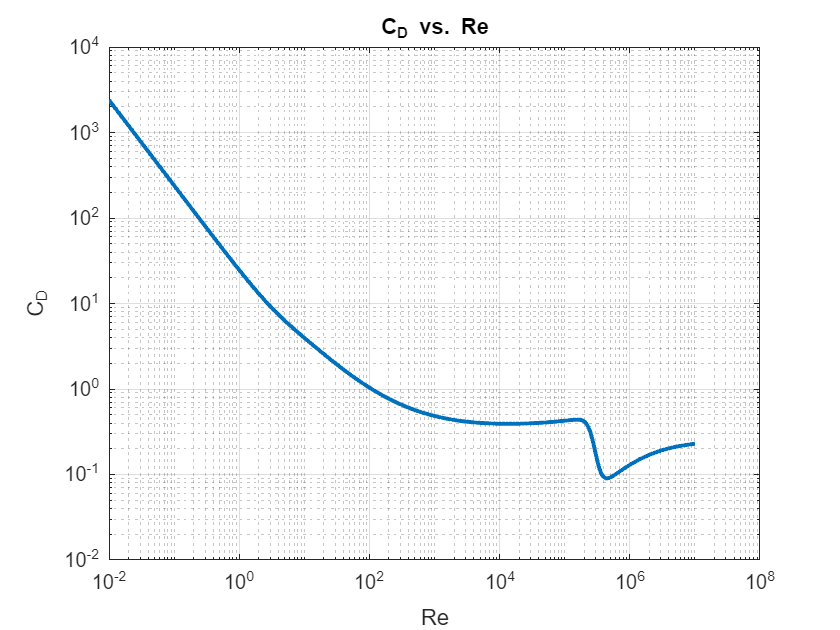

% Define a range of Reynolds numbers on a logarithmic scale
Re_range = logspace(-2, 7, 1000);

% Calculate the drag coefficient for each Reynolds number
CD_values = arrayfun(@(Re) calculate_CD(Re), Re_range);

% Plot the drag coefficient against Reynolds numbers
figure;
loglog(Re_range, CD_values, 'LineWidth', 2);
grid on;
xlabel('Re');
ylabel('C_D');
title('C_D vs. Re');

Since the plot looks good, we'll continue on implementing the differential eqautions.

Define solver params

% Time step
dt = 0.01;  % s
t_final = 100;  % total time of simulation (s)
time = 0:dt:t_final;

% Initial conditions
V = 0;  % m/s
h = h0;  % m

% Arrays to store the results
V_array = zeros(1, length(time));
h_array = zeros(1, length(time));

Solver

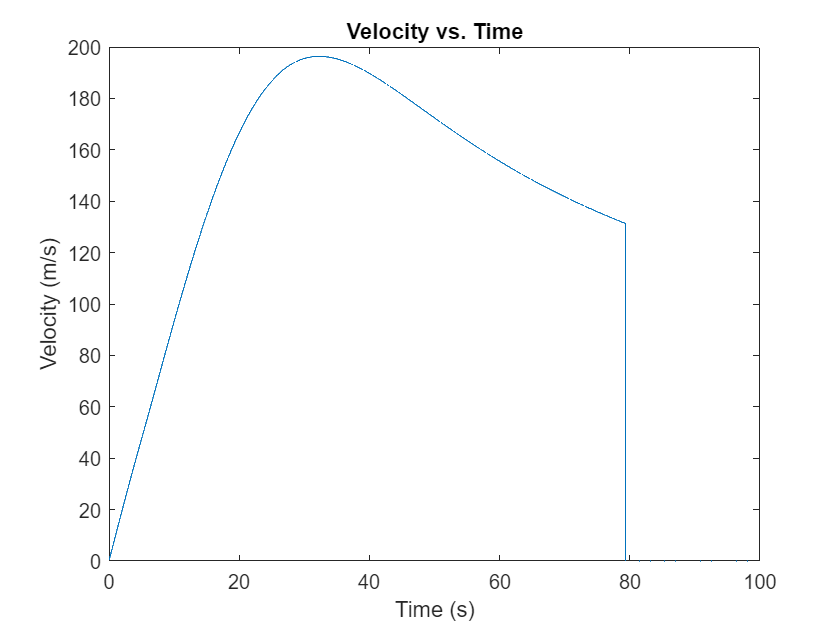

% Euler's method
for i = 1:length(time)
    % Interpolate the atmospheric conditions at the current altitude
    rho_current = ppval(height_rho, h);
    mu_current = ppval(height_mu, h);
    
    Re = calculate_Re(rho_current, V, d, mu_current);
    
    CD = calculate_CD(Re);
    
    % Drag force
    D = 0.5 * CD * rho_current * V^2 * A;
    if V == 0  % When starting, Re is NaN
        D = 0;
    end
    
    % Update
    V = V + dt * (g - D / m);
    h = h - dt * V;
    
    % Store results
    V_array(i) = V;
    h_array(i) = h;
    
    % Stop if the ball hits the ground
    if h <= 0
        break;
    end
end

% Plot the results
figure(2);
plot(time, V_array);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time');

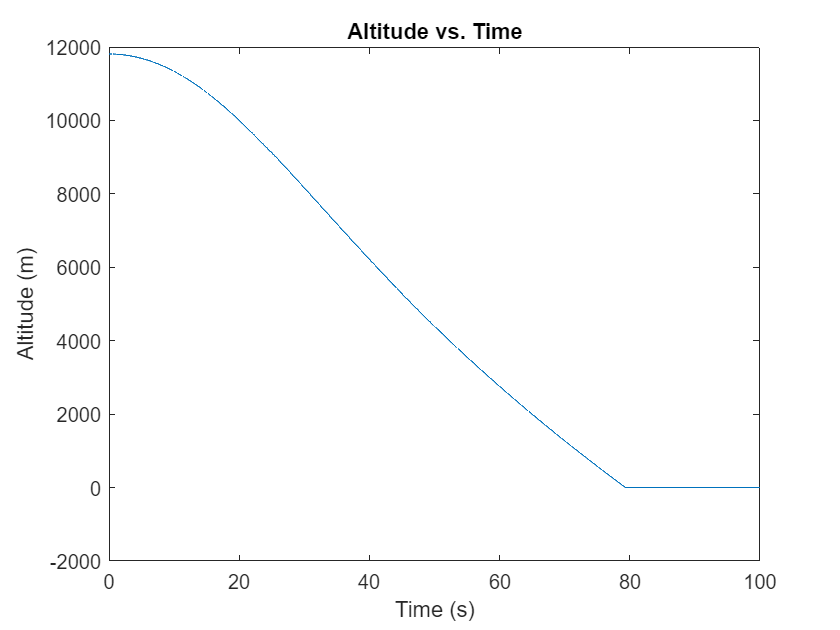

figure(3);
plot(time, h_array);
xlabel('Time (s)');
ylabel('Altitude (m)');
title('Altitude vs. Time');

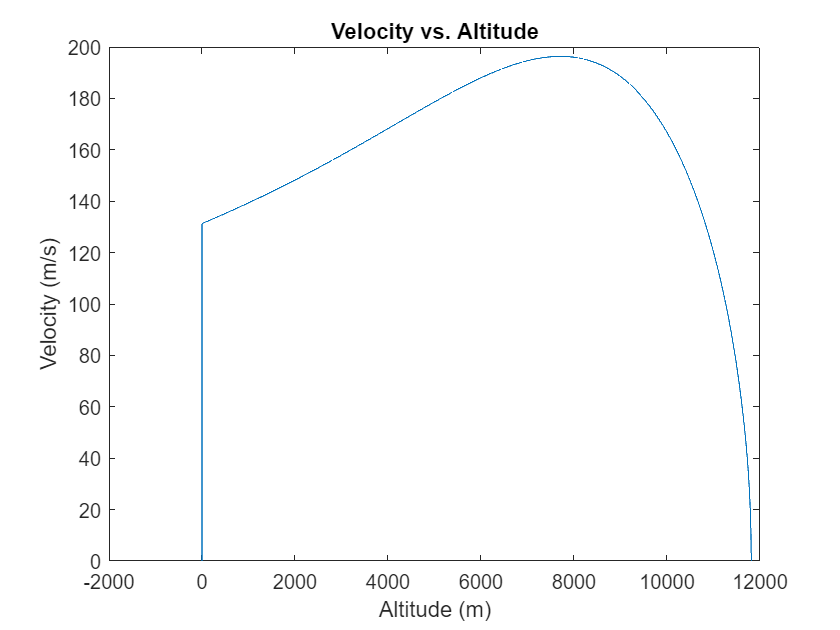

figure(4);
plot(h_array, V_array);
xlabel('Altitude (m)');
ylabel('Velocity (m/s)');
title('Velocity vs. Altitude');

Define the function for calculating $C_D$ from $Re$

function CD = calculate_CD(Re)
    term1 = 24 / Re;
    term2 = (2.6 * (Re / 5.0)) / (1 + (Re / 5.0)^1.52);
    term3 = (0.411 * (Re / (2.63 * 10^5))^(-7.94)) / (1 + (Re / (2.63 * 10^5))^(-8.00));
    term4 = 0.25 * (Re / 10^6) / (1 + (Re / 10^6));

    CD = term1 + term2 + term3 + term4;
end

$Re$ calculation

function Re = calculate_Re(rho, V, d, mu)
    Re = rho * V * d / mu;
end